# Calibrate Credit Risk Function

## Generalized Logistic Function


$$q_t = \underline q + \left(\overline q - \underline q\right) \left[ \frac{1}{1 + \exp-\frac{z-\mu}{\sigma} } \right]^{\exp\nu}$$


## Clear Workspace


close all
clear

figure( );


## Vector of Macro Conditions


distance_between_car_and_car_min = linspace(0.001, 0.05, 100);


## Choose Parameters and Plot Function

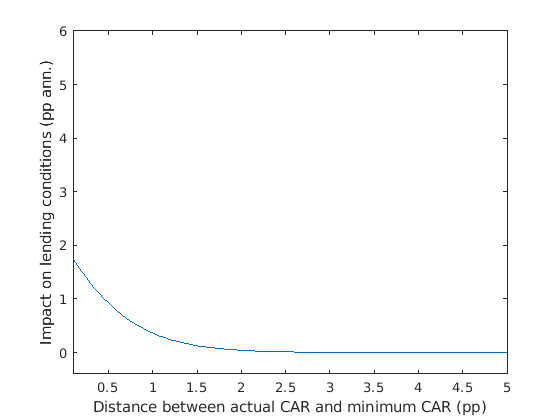

% Location parameter
mu = 0.005 ;

% Scale parameter (dispersion)
sigma = 0.007;

% Shape parameter (symmetry)
nu = 0.5; % Do not change

% Lower bound
low = -0.005; % Do not change

% Upper bound
high = 0.015;

%% Plot CDF 

% subplot(2, 1, 1);
plot(100*distance_between_car_and_car_min, 400*glogc1(-distance_between_car_and_car_min, mu, sigma, nu, low, high));
set(gca( ), "XLim", 100*[min(distance_between_car_and_car_min), max(distance_between_car_and_car_min)], "YLim", 400*[-0.001, high]);
xline(0, "LineWidth", 2);
xlabel("Distance between actual CAR and minimum CAR (pp)");
ylabel("Impact on lending conditions (pp ann.)");


% Plot PDF

% subplot(2, 1, 2);
% plot(z, glogd(-z, -mu, sigma, nu, low, high));
% set(gca( ), "XLim", [min(z), max(z)]);
% xline(0, "LineWidth", 2);
% xlabel("Output Gap");
% ylabel("Credit Event Impact");
